**3.1 Harmonic Detection**

**Part 1** : Loading the given Signal and plot

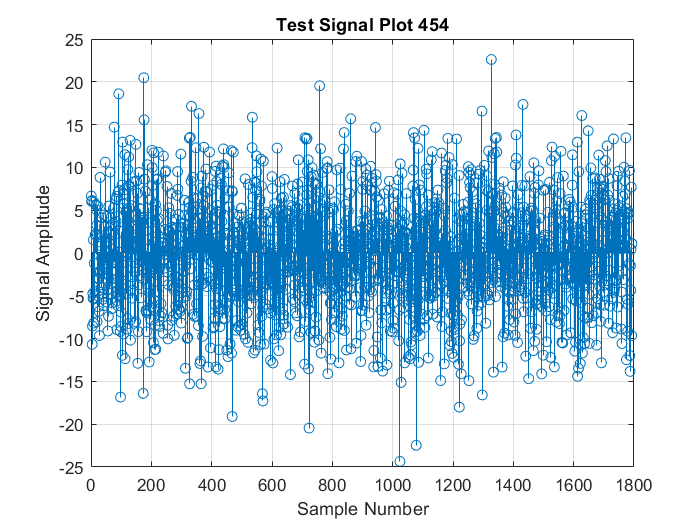

%Load the test signal corresponding to index number 210454G
load('signal454.mat', 'xn_test');  % Load the signal from the .mat file

% Plot the discrete signal
figure;             
stem(xn_test);       
xlabel('Sample Number');  
ylabel('Signal Amplitude');  
title('Test Signal Plot 454');   
grid on;             

**Part 2 **: Constructing Subsets of the signal and plot

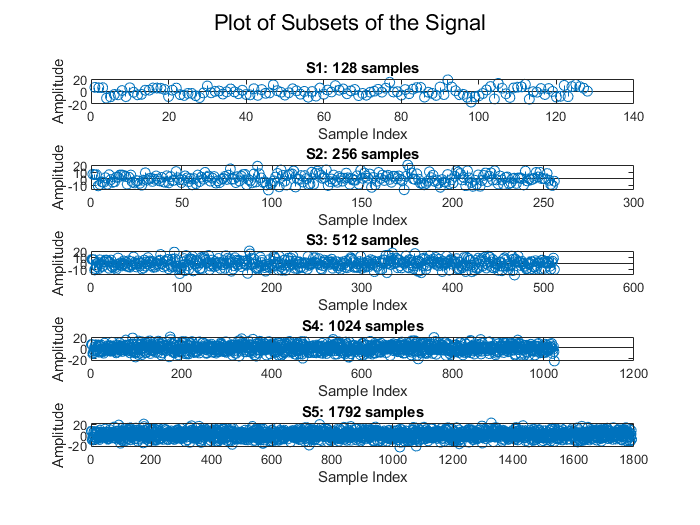

fs = 128;           % Sampling rate (Hz)
n_total = 1792;     % Number of samples to consider

% Subsets of the signal
S1 = xn_test(1:128);
S2 = xn_test(1:256);
S3 = xn_test(1:512);
S4 = xn_test(1:1024);
S5 = xn_test(1:1792);

% Create a figure for the subplots
figure;  

% Subplot 1: Plot S1 (128 samples)
subplot(5, 1, 1);
stem(S1);
title('S1: 128 samples');
xlabel('Sample Index');
ylabel('Amplitude');

% Subplot 2: Plot S2 (256 samples)
subplot(5, 1, 2);
stem(S2);
title('S2: 256 samples');
xlabel('Sample Index');
ylabel('Amplitude');

% Subplot 3: Plot S3 (512 samples)
subplot(5, 1, 3);
stem(S3);
title('S3: 512 samples');
xlabel('Sample Index');
ylabel('Amplitude');

% Subplot 4: Plot S4 (1024 samples)
subplot(5, 1, 4);
stem(S4);
title('S4: 1024 samples');
xlabel('Sample Index');
ylabel('Amplitude');

% Subplot 5: Plot S5 (1792 samples)
subplot(5, 1, 5);
stem(S5);
title('S5: 1792 samples');
xlabel('Sample Index');
ylabel('Amplitude');

% Add a global title for the entire figure
sgtitle('Plot of Subsets of the Signal');

**Part 3**: Apply DFT to each subset of samples and display the magnitude of the reulting DFT sequences so as to identify the harmonics

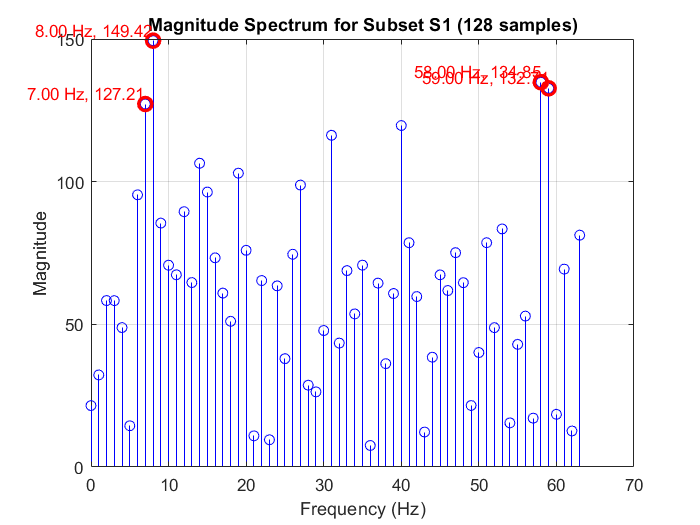

% Create figure for Subset S1
figure;
N1 = length(S1);
Xk1 = fft(S1);                % Compute DFT using FFT
f1 = (0:N1-1)*(fs/N1);        % Frequency vector for plotting
magnitude1 = abs(Xk1);        % Magnitude of DFT

stem(f1(1:N1/2), magnitude1(1:N1/2), 'b');  % Plot up to fs/2 (Nyquist frequency)
hold on;

% Find and mark the top 4 harmonics
[~, idx1] = sort(magnitude1(1:N1/2), 'descend'); % Sort magnitudes in descending order
top4_idx1 = idx1(1:4); % Indices of top 4 harmonics

plot(f1(top4_idx1), magnitude1(top4_idx1), 'ro', 'MarkerSize', 8, 'LineWidth', 2); % Mark top 4 harmonics
for k = 1:4
    text(f1(top4_idx1(k)), magnitude1(top4_idx1(k)), sprintf('%.2f Hz, %.2f', f1(top4_idx1(k)), magnitude1(top4_idx1(k))), ...
        'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'Color', 'red');
end

xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Magnitude Spectrum for Subset S1 (128 samples)');
grid on;
hold off;

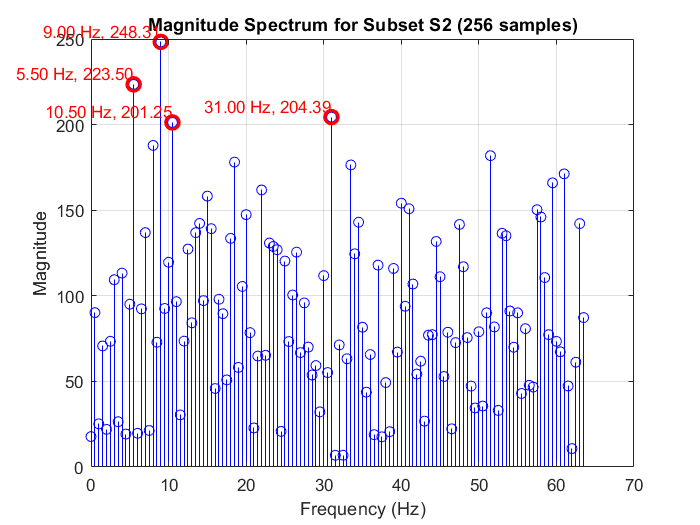


% Create figure for Subset S2
figure;
N2 = length(S2);
Xk2 = fft(S2);                % Compute DFT using FFT
f2 = (0:N2-1)*(fs/N2);        % Frequency vector for plotting
magnitude2 = abs(Xk2);        % Magnitude of DFT

stem(f2(1:N2/2), magnitude2(1:N2/2), 'b');  % Plot up to fs/2 (Nyquist frequency)
hold on;

% Find and mark the top 4 harmonics
[~, idx2] = sort(magnitude2(1:N2/2), 'descend'); % Sort magnitudes in descending order
top4_idx2 = idx2(1:4); % Indices of top 4 harmonics

plot(f2(top4_idx2), magnitude2(top4_idx2), 'ro', 'MarkerSize', 8, 'LineWidth', 2); % Mark top 4 harmonics
for k = 1:4
    text(f2(top4_idx2(k)), magnitude2(top4_idx2(k)), sprintf('%.2f Hz, %.2f', f2(top4_idx2(k)), magnitude2(top4_idx2(k))), ...
        'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'Color', 'red');
end

xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Magnitude Spectrum for Subset S2 (256 samples)');
grid on;
hold off;

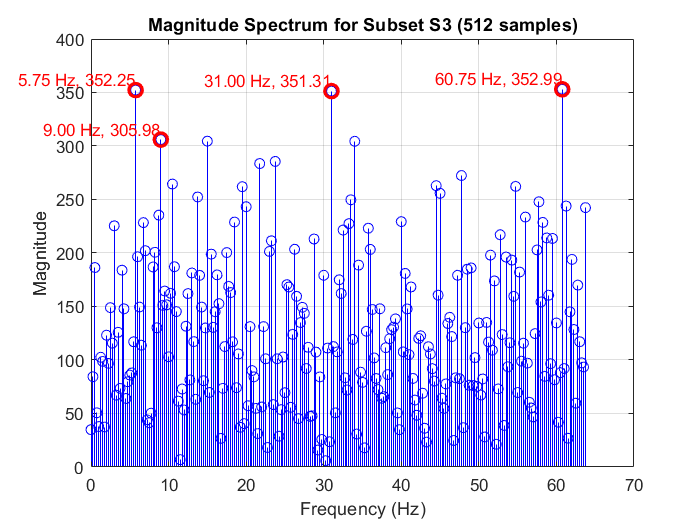


% Create figure for Subset S3
figure;
N3 = length(S3);
Xk3 = fft(S3);                % Compute DFT using FFT
f3 = (0:N3-1)*(fs/N3);        % Frequency vector for plotting
magnitude3 = abs(Xk3);        % Magnitude of DFT

stem(f3(1:N3/2), magnitude3(1:N3/2), 'b');  % Plot up to fs/2 (Nyquist frequency)
hold on;

% Find and mark the top 4 harmonics
[~, idx3] = sort(magnitude3(1:N3/2), 'descend'); % Sort magnitudes in descending order
top4_idx3 = idx3(1:4); % Indices of top 4 harmonics

plot(f3(top4_idx3), magnitude3(top4_idx3), 'ro', 'MarkerSize', 8, 'LineWidth', 2); % Mark top 4 harmonics
for k = 1:4
    text(f3(top4_idx3(k)), magnitude3(top4_idx3(k)), sprintf('%.2f Hz, %.2f', f3(top4_idx3(k)), magnitude3(top4_idx3(k))), ...
        'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'Color', 'red');
end

xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Magnitude Spectrum for Subset S3 (512 samples)');
grid on;
hold off;

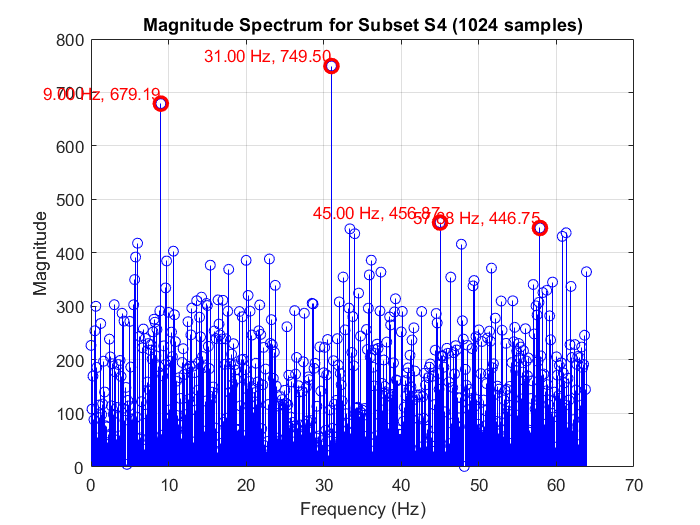


% Create figure for Subset S4
figure;
N4 = length(S4);
Xk4 = fft(S4);                % Compute DFT using FFT
f4 = (0:N4-1)*(fs/N4);        % Frequency vector for plotting
magnitude4 = abs(Xk4);        % Magnitude of DFT

stem(f4(1:N4/2), magnitude4(1:N4/2), 'b');  % Plot up to fs/2 (Nyquist frequency)
hold on;

% Find and mark the top 4 harmonics
[~, idx4] = sort(magnitude4(1:N4/2), 'descend'); % Sort magnitudes in descending order
top4_idx4 = idx4(1:4); % Indices of top 4 harmonics

plot(f4(top4_idx4), magnitude4(top4_idx4), 'ro', 'MarkerSize', 8, 'LineWidth', 2); % Mark top 4 harmonics
for k = 1:4
    text(f4(top4_idx4(k)), magnitude4(top4_idx4(k)), sprintf('%.2f Hz, %.2f', f4(top4_idx4(k)), magnitude4(top4_idx4(k))), ...
        'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'Color', 'red');
end

xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Magnitude Spectrum for Subset S4 (1024 samples)');
grid on;
hold off;

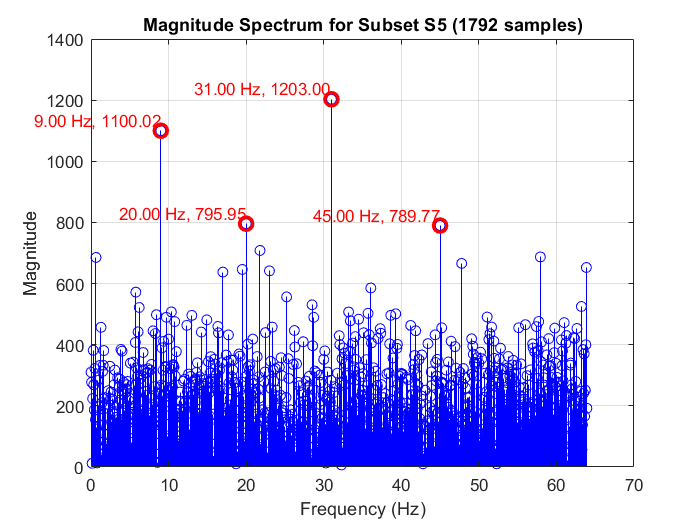


% Create figure for Subset S5
figure;
N5 = length(S5);
Xk5 = fft(S5);                % Compute DFT using FFT
f5 = (0:N5-1)*(fs/N5);        % Frequency vector for plotting
magnitude5 = abs(Xk5);        % Magnitude of DFT

stem(f5(1:N5/2), magnitude5(1:N5/2), 'b');  % Plot up to fs/2 (Nyquist frequency)
hold on;

% Find and mark the top 4 harmonics
[~, idx5] = sort(magnitude5(1:N5/2), 'descend'); % Sort magnitudes in descending order
top4_idx5 = idx5(1:4); % Indices of top 4 harmonics

plot(f5(top4_idx5), magnitude5(top4_idx5), 'ro', 'MarkerSize', 8, 'LineWidth', 2); % Mark top 4 harmonics
for k = 1:4
    text(f5(top4_idx5(k)), magnitude5(top4_idx5(k)), sprintf('%.2f Hz, %.2f', f5(top4_idx5(k)), magnitude5(top4_idx5(k))), ...
        'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'Color', 'red');
end

xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Magnitude Spectrum for Subset S5 (1792 samples)');
grid on;
hold off;

**Part 4**: DFT averaing method

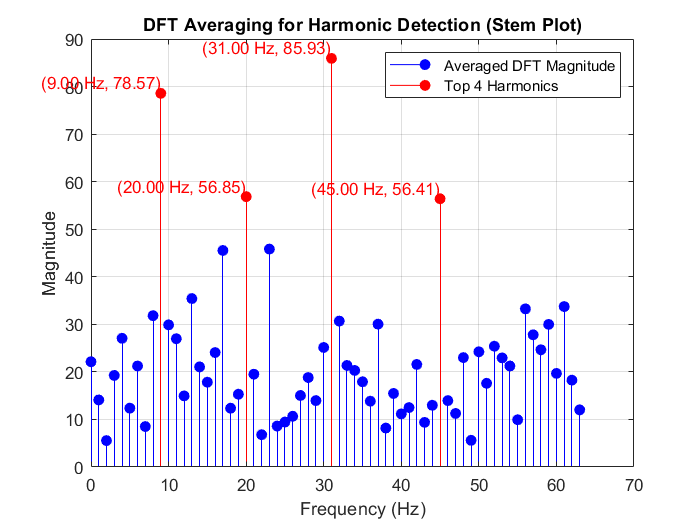

fs = 128;  % Sampling frequency in Hz
K = 128;   % Length of each subset
L = 14;    % Number of subsets

% Ensure the signal length matches the total number of samples required (L * K)
N = L * K;  % Total length of signal for DFT averaging (1792 in this case)
xn_test = xn_test(1:N);  % Truncate or use the first N samples of the signal

% Initialize variables to store the DFT results
X_avg = zeros(1, K);  % Initialize for averaging DFTs

% Loop over each subset and calculate the DFT, then accumulate
for l = 1:L
    subset = xn_test((l-1)*K+1:l*K);  % Get the current subset
    X_subset = fft(subset);           % Compute DFT of the subset
    X_avg = X_avg + X_subset;         % Accumulate the DFTs
end

% Calculate the averaged DFT
X_avg = X_avg / L;

% Frequency vector for plotting
f = (0:K-1)*(fs/K);

% Calculate the magnitude of the averaged DFT
X_avg_mag = abs(X_avg);

% Plot the magnitude of the averaged DFT using a stem plot
figure;
stem(f(1:K/2), X_avg_mag(1:K/2), 'b', 'filled');  % Plot up to Nyquist frequency (fs/2)
hold on;

% Identify the top 4 harmonics (frequencies with the highest magnitude)
X_half = X_avg_mag(1:K/2);  % Only consider up to the Nyquist frequency
[~, idx] = sort(X_half, 'descend');  % Sort in descending order of magnitude

% Get the indices of the top 4 peaks
top4_indices = idx(1:4);

% Convert these indices to the corresponding frequencies
top4_frequencies = f(top4_indices);
top4_magnitudes = X_half(top4_indices);

% Plot the top 4 harmonics in red and add text annotations
stem(f(top4_indices), X_avg_mag(top4_indices), 'r', 'filled');  % Red for top harmonics
for i = 1:4
    text(f(top4_indices(i)), X_avg_mag(top4_indices(i)), ...
         sprintf('(%.2f Hz, %.2f)', f(top4_indices(i)), X_avg_mag(top4_indices(i))), ...
         'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'Color', 'red');
end

xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('DFT Averaging for Harmonic Detection (Stem Plot)');
legend('Averaged DFT Magnitude', 'Top 4 Harmonics');
grid on;
hold off;


% Display the top 4 harmonic frequencies and their magnitudes
disp('Top 4 harmonic frequencies and their magnitudes (Hz and magnitude):');

Top 4 harmonic frequencies and their magnitudes (Hz and magnitude):


for i = 1:4
    fprintf('Frequency: %.2f Hz, Magnitude: %.2f\n', top4_frequencies(i), top4_magnitudes(i));
end

Frequency: 31.00 Hz, Magnitude: 85.93
Frequency: 9.00 Hz, Magnitude: 78.57
Frequency: 20.00 Hz, Magnitude: 56.85
Frequency: 45.00 Hz, Magnitude: 56.41


**Part 5 : **smallest value of L such that the four peaks that correspond to the four harmonics not greater than 64 remain clearly visible

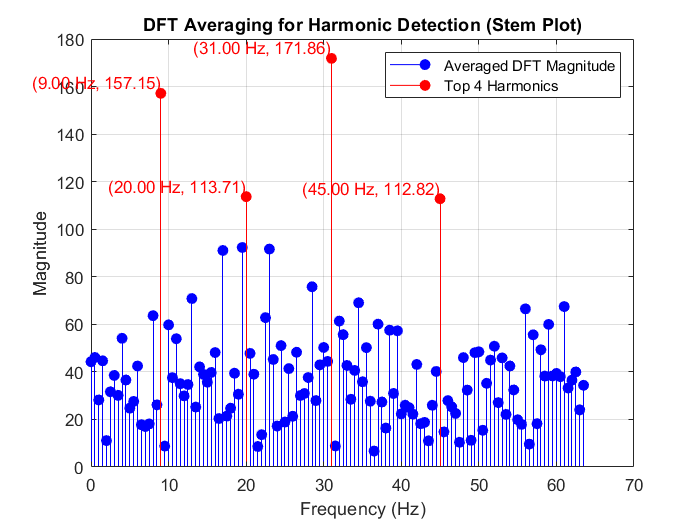

fs = 128;  % Sampling frequency in Hz
K = 256;   % Length of each subset
L = 7;    % Number of subsets

% Ensure the signal length matches the total number of samples required (L * K)
N = L * K;  % Total length of signal for DFT averaging (1792 in this case)
xn_test = xn_test(1:N);  % Truncate or use the first N samples of the signal

% Initialize variables to store the DFT results
X_avg = zeros(1, K);  % Initialize for averaging DFTs

% Loop over each subset and calculate the DFT, then accumulate
for l = 1:L
    subset = xn_test((l-1)*K+1:l*K);  % Get the current subset
    X_subset = fft(subset);           % Compute DFT of the subset
    X_avg = X_avg + X_subset;         % Accumulate the DFTs
end

% Calculate the averaged DFT
X_avg = X_avg / L;

% Frequency vector for plotting
f = (0:K-1)*(fs/K);

% Calculate the magnitude of the averaged DFT
X_avg_mag = abs(X_avg);

% Plot the magnitude of the averaged DFT using a stem plot
figure;
stem(f(1:K/2), X_avg_mag(1:K/2), 'b', 'filled');  % Plot up to Nyquist frequency (fs/2)
hold on;

% Identify the top 4 harmonics (frequencies with the highest magnitude)
X_half = X_avg_mag(1:K/2);  % Only consider up to the Nyquist frequency
[~, idx] = sort(X_half, 'descend');  % Sort in descending order of magnitude

% Get the indices of the top 4 peaks
top4_indices = idx(1:4);

% Convert these indices to the corresponding frequencies
top4_frequencies = f(top4_indices);
top4_magnitudes = X_half(top4_indices);

% Plot the top 4 harmonics in red and add text annotations
stem(f(top4_indices), X_avg_mag(top4_indices), 'r', 'filled');  % Red for top harmonics
for i = 1:4
    text(f(top4_indices(i)), X_avg_mag(top4_indices(i)), ...
         sprintf('(%.2f Hz, %.2f)', f(top4_indices(i)), X_avg_mag(top4_indices(i))), ...
         'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'Color', 'red');
end

xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('DFT Averaging for Harmonic Detection (Stem Plot)');
legend('Averaged DFT Magnitude', 'Top 4 Harmonics');
grid on;
hold off;


% Display the top 4 harmonic frequencies and their magnitudes
disp('Top 4 harmonic frequencies and their magnitudes (Hz and magnitude):');

Top 4 harmonic frequencies and their magnitudes (Hz and magnitude):


for i = 1:4
    fprintf('Frequency: %.2f Hz, Magnitude: %.2f\n', top4_frequencies(i), top4_magnitudes(i));
end

Frequency: 31.00 Hz, Magnitude: 171.86
Frequency: 9.00 Hz, Magnitude: 157.15
Frequency: 20.00 Hz, Magnitude: 113.71
Frequency: 45.00 Hz, Magnitude: 112.82
